# Sensor Calibration from Experimental Data

## Processing of Experimental Data

#### Averaging:

In MATLAB, find the mean value of each ADC channel’s readings for the duration. 

load sensor_data.mat % load sensor data
ADC1AVE = mean(sensor1(1,end-9:end)) % average last 10 data points

ADC1AVE = 59206

ADC2AVE = mean(sensor2(1,end-9:end)) % average last 10 data points

ADC2AVE = 6.3965e+04

Write the ground truth temperatures hot or cold associated, respectively, with each average value.

TEMP1 = 32; % ground truth for cold 
TEMP2 = 610; % ground truth for hot

#### Linear Fit Hypothesis

The relationship between ADC readings and temperature is linear as follows:

TEMP = SL × ADC + VI

Where SL is the slope and V I the vertical intercept of the line. The unknown parameters SL and V I are determined next.

#### Calculation of Parameters

The two average readings and their respective ground truth temperatures provide two

points on the above line:

TEMP1 = SL × ADC1 + VI

TEMP2 = SL × ADC2 + VI

In MATLAB, using the function inv(A) compute the parameters of the linear fit:

A = [ADC1AVE 1; ADC2AVE 1]; % matrix for linear equations
params = inv(A) * [TEMP1; TEMP2] % slope and intercept parameters

params = 1.0e+03 *

    0.0001
   -7.1582


#### Graph

Plot of the line and overlay the two average points used for the sensor calibration.

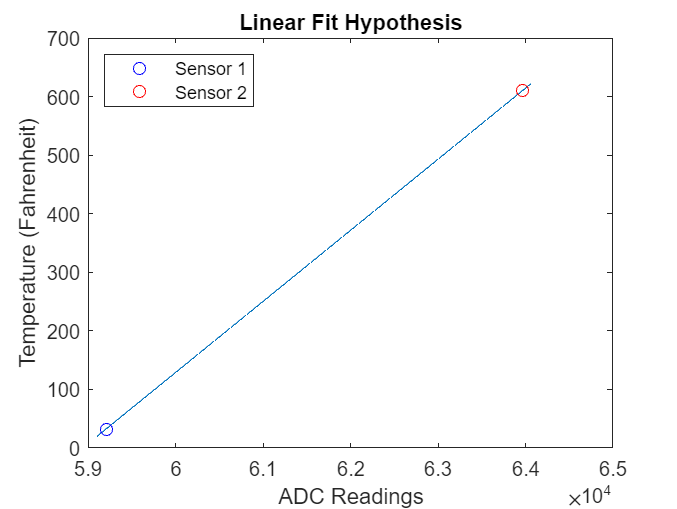

x = ADC1AVE-100:ADC2AVE+100; % create range of ADC values 
y = params(1,1) * x + params(2,1); % calculate temperatures based on parameters
plot(x,y) % plot line
hold on
p1 = plot(ADC1AVE,TEMP1,'bo'); % plot low temperature reading
p2 = plot(ADC2AVE,TEMP2,'ro'); % plot high temperatuer reading
hold off
title("Linear Fit Hypothesis")
xlabel("ADC Readings")
ylabel("Temperature (Fahrenheit)")
data_points = [p1 p2]; % to create legend for only sensor data points
legend(data_points, "Sensor 1", "Sensor 2", 'Location','northwest')